Baudrate = 115200;
serialportlist

Undefined function or variable 'serialportlist'.

RpLidar = serialport("COM3", Baudrate, "Timeout", 1, "Parity","odd")
setDTR(RpLidar,false)







% Reset (leave protected mode)
resetStr = 'A540'
resetStrData = sscanf(resetStr, '%2x')
write(RpLidar,resetStrData,"uint8")
readReset = read(RpLidar, 5, "uint8")
dec2hex(readReset)


% Start scan
startStr = 'A521'
startStrData = sscanf(startStr, '%2x')
write(RpLidar,startStr,"uint8")
scandata = read(RpLidar, 59, "uint8")
RpLidar.NumBytesAvailable
dec2bin(scandata, 8)
dec2hex(scandata)

%flush(RpLidar, "output")


% Disconnect
clear RpLidar


stopStr = 'A525'
stopStrData = sscanf(stopStr, '%2x')
write(RpLidar,stopStr,"uint8")
readStop = read(RpLidar, 8, "uint8")
dec2hex(readStop)

% health
str = 'A552';
data = sscanf(str, '%2x');
hexStrWriteData = dec2hex(data)

write(RpLidar, data, "uint8");
readData = read(RpLidar, 10,"uint8");
hexStr = dec2hex(readData)


getInfoStr = 'A550'
getInfoStrData = sscanf(getInfoStr, '%2x')
write(RpLidar,getInfoStrData,"uint8")
readInfo = read(RpLidar, 20,"uint8")
hexStr = dec2hex(readInfo)


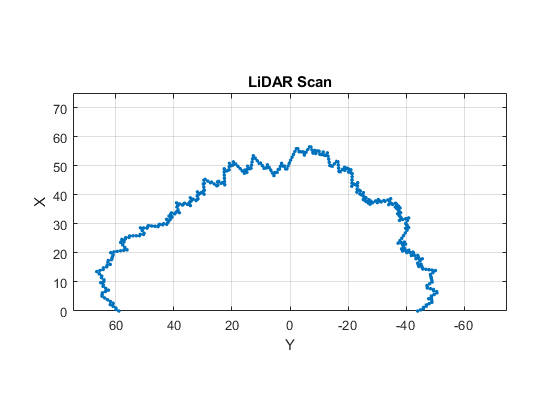

start = randi([40, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end
ranges;


angles = linspace(-pi/2, pi/2, numel(ranges));
scan = lidarScan(ranges, angles);
plot(scan)

## Plot with psuedo randomly generated values


start = randi([15, 20],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end



theta = linspace(0, 360, 360);
rho = randi([0, 10], 360, 1);
theta_rad = deg2rad(theta);
polarplot(theta_rad, ranges, '.')
hold on

% obstacle detection
detection_range = 15

detection_range = 15

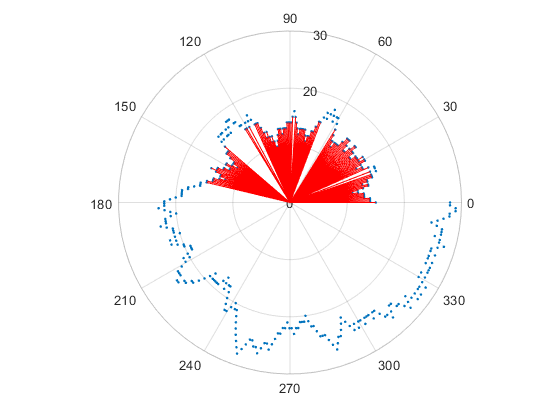

for i = 1:360
    if  abs(ranges(i)) <= detection_range
        line_angle = [theta_rad(i) theta_rad(i)];
        line_range = [0 ranges(i)];
        polarplot(line_angle, line_range, 'r')
    end
end
hold off

## Shape 1 Square without obstacle

% Generate cartesian square
x_v1 = ones(1,45) * 20;
x_v2 = linspace(20, -20, 90);
x_v3 = ones(1, 90) * (-20);
x_v4 = linspace(-20, 20, 90);
x_v5 = ones(1,45) * 20;
x_square = [x_v1 x_v2 x_v3 x_v4 x_v5];

y_v1 = linspace(0, 20, 45);
y_v2 = ones(1,90) * 20;
y_v3 = linspace(20, -20, 90);
y_v4 = ones(1,90) * (-20);
y_v5 = linspace(-20, 0, 45);
y_square = [y_v1 y_v2 y_v3 y_v4 y_v5];


% generate polar cordinates
[theta_square, rho_square] = cart2pol(x_square, y_square);

%plot figure
figure
polarplot(theta_square, rho_square, '.')
hold on


% obstacle detection
detection_range = 15

detection_range = 15

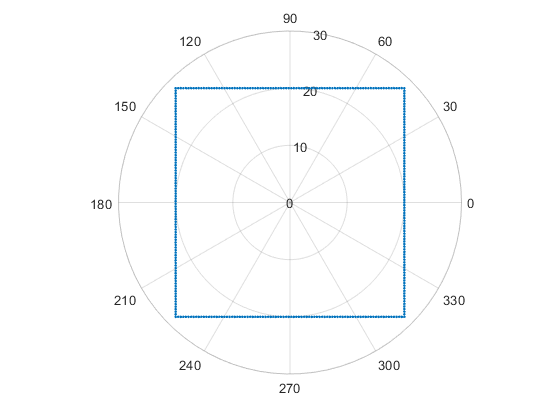

for i = 1:360
    if  abs(rho_square(i)) <= detection_range
        line_angle = [theta_square(i) theta_square(i)];
        line_range = [0 rho_square(i)];
        polarplot(line_angle, line_range, 'r')
    end
end
hold off

## Shape 2 Square with obstacle

theta_square_obst = theta_square;
rho_square_obst = rho_square;

rho_square_obst(30:60) = 15;

% Plot square
figure
polarplot(theta_square_obst, rho_square_obst, '.')
hold on

%detection
detection_range = 15

detection_range = 15

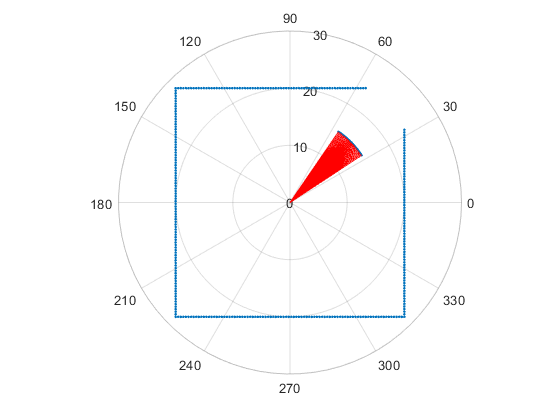

for i = 1:360
    if  abs(rho_square_obst(i)) <= detection_range
        line_angle = [theta_square_obst(i) theta_square_obst(i)];
        line_range = [0 rho_square_obst(i)];
        polarplot(line_angle, line_range, 'r')
    end
end
hold off